# CAPÍTULO 14 - CÁLCULOS DE FATIGA

Calcula amplitudes y tensiones medias, aplica correcciones de la pieza y obtiene el factor de seguridad de varios ciclos críticos.

Dimensión: comprobación por puntos a partir de extremos de tensión normal y cortante. Un marco espacial puede proporcionar esos esfuerzos, pero aquí no se resuelve su geometría ni un ciclo tensorial no proporcional.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

Cada fila de ciclos contiene [sigmaMax sigmaMin tauMax tauMin] en Pa para un punto crítico. Knormal y Kcortante son correcciones globales sobre la amplitud. psiNormal y psiCortante describen la sensibilidad a tensión media. Se admiten escalares comunes a todas las filas.

ciclos=[120 -80 35 -35; 90 -50 50 -20]*1e6;
limiteFatigaNormal=180e6; limiteFatigaCortante=105e6;
limiteTraccion=340e6; limiteCompresion=340e6; limiteCortante=195e6;
Knormal=1.6; Kcortante=1.4; psiNormal=.15; psiCortante=.10;
nRequerido=1.5;

## 2. Amplitud, media y seguridad


$$\sigma_a=\frac{\sigma_{max}-\sigma_{min}}2,\qquad \sigma_m=\frac{\sigma_{max}+\sigma_{min}}2$$



$$n_{\sigma,f}=\frac{\sigma_{-1}}{K_\sigma\sigma_a+\psi_\sigma\sigma_m},\qquad n_{\sigma,y}=\frac{\sigma_Y}{K_\sigma\sigma_a+|\sigma_m|}$$


La expresión de fluencia escrita arriba corresponde a límites iguales en tracción y compresión. Con límites diferentes, el código toma el menor factor de ambos extremos del ciclo.


$$n_\sigma=\min(n_{\sigma,f},n_{\sigma,y}),\quad \frac1{n^2}=\frac1{n_\sigma^2}+\frac1{n_\tau^2}$$


La corrección K se aplica a la amplitud. Para compresión se utiliza su límite resistente. Si la recta de fatiga no limita el ciclo, se mantiene la comprobación estática. La combinación normal-cortante no sustituye una ley de daño multiaxial dependiente de trayectoria.

assert(size(ciclos,2)==4 && all(isfinite(ciclos(:))) && ...
    all(ciclos(:,1)>=ciclos(:,2) & ciclos(:,3)>=ciclos(:,4)),'Ciclos invalidos.');
assert(all([limiteFatigaNormal limiteFatigaCortante limiteTraccion limiteCompresion ...
    limiteCortante Knormal Kcortante nRequerido]>0) && psiNormal>=0 && psiCortante>=0,'Coeficientes invalidos.');
sa=(ciclos(:,1)-ciclos(:,2))/2; sm=(ciclos(:,1)+ciclos(:,2))/2;
ta=(ciclos(:,3)-ciclos(:,4))/2; tm=(ciclos(:,3)+ciclos(:,4))/2;
dn=Knormal.*sa+psiNormal.*sm; dt=Kcortante.*ta+psiCortante.*tm;
nFatN=limiteFatigaNormal./max(dn,realmin); nFatT=limiteFatigaCortante./max(dt,realmin);
nEstN=min(limiteTraccion./max(Knormal.*sa+sm,realmin), ...
    limiteCompresion./max(Knormal.*sa-sm,realmin));
nEstT=limiteCortante./max(Kcortante.*ta+abs(tm),realmin);
nNormal=min(nFatN,nEstN); nCortante=min(nFatT,nEstT);
nCombinado=1./sqrt(1./nNormal.^2+1./nCortante.^2);
resultado=table((1:size(ciclos,1))',sa/1e6,sm/1e6,ta/1e6,tm/1e6,nNormal,nCortante,nCombinado,nCombinado>=nRequerido, ...
    'VariableNames',{'Punto','sigmaA_MPa','sigmaM_MPa','tauA_MPa','tauM_MPa','nNormal','nCortante','nCombinado','Cumple'});
disp(resultado);

    Punto    sigmaA_MPa    sigmaM_MPa    tauA_MPa    tauM_MPa    nNormal    nCortante    nCombinado    Cumple
    _____    __________    __________    ________    ________    _______    _________    __________    ______

      1         100            20           35           0       1.1043      2.1429       0.98162      false 
      2          70            20           35          15       1.5652      2.0792        1.2505      false 



## 3. Ciclos y diagrama de amplitudes

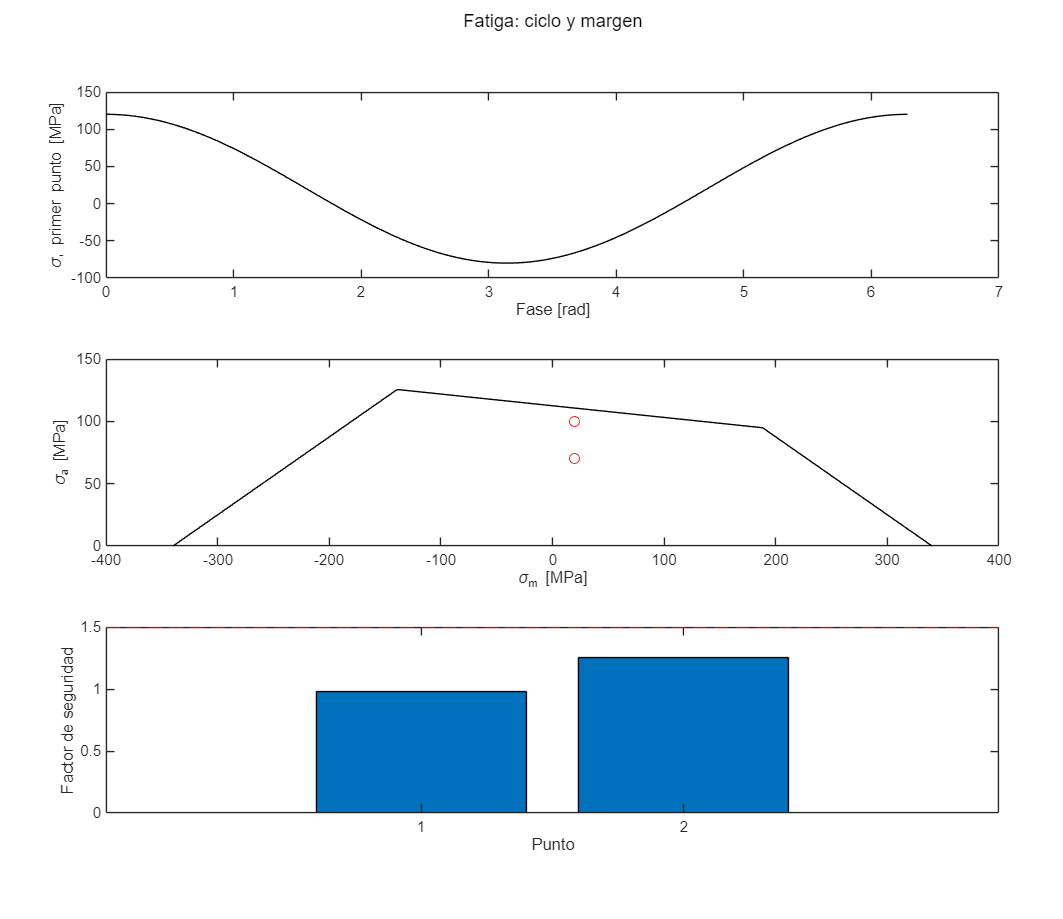

[figura,ejes]=rm_figura(3,'Fatiga: ciclo y margen');
fase=linspace(0,2*pi,301); plot(ejes(1),fase,(sm(1)+sa(1)*cos(fase))/1e6,'k-');
xlabel(ejes(1),'Fase [rad]'); ylabel(ejes(1),'\sigma, primer punto [MPa]');
medias=linspace(-limiteCompresion,limiteTraccion,401);
ampFat=(limiteFatigaNormal-psiNormal*medias)/Knormal;
ampEst=min((limiteTraccion-medias)/Knormal,(limiteCompresion+medias)/Knormal);
amplitudes=max(0,min(ampFat,ampEst));
plot(ejes(2),medias/1e6,amplitudes/1e6,'k-',sm/1e6,sa/1e6,'ro');
xlabel(ejes(2),'\sigma_m [MPa]'); ylabel(ejes(2),'\sigma_a [MPa]');
bar(ejes(3),nCombinado); yline(ejes(3),nRequerido,'r--');
xlabel(ejes(3),'Punto'); ylabel(ejes(3),'Factor de seguridad');

## Funciones utilizadas

min: selecciona el criterio más restrictivo. Aquí compara fatiga y fluencia.

sqrt: calcula una raíz cuadrada. Aquí combina las dos reservas mediante la relación empírica.

cos: describe una oscilación periódica. Aquí dibuja un ciclo representativo; la evaluación utiliza sus extremos.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Ciclos estacionarios caracterizados por sus extremos, límites de fatiga y coeficientes conocidos. Combina tensión normal y cortante mediante una relación empírica de seguridad. No estima daño acumulado, espectros variables ni vida finita sin datos experimentales.

Conexión con lo anterior: Las tensiones máximas y mínimas se pueden obtener de los capítulos 5, 6 y 9. La revisión de fluencia acompaña a la de fatiga.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 14: calculo completado.');

Capitulo 14: calculo completado.
